## DEFINIR VARIAVEIS

tau = 100;
km=30;

## DEFINIR SISTEMAS

sysposma = tf(1, [tau km 0]);
sysvelma = tf(1, [tau km]);

## STEP APLICADO NO SISTEMA

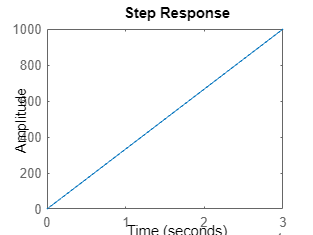

step(sysposma); %instavel vai p infinito polo zero

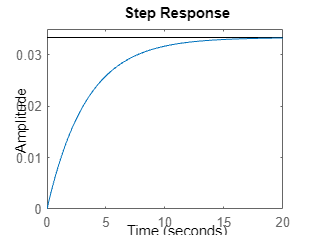

step(sysvelma); %estavel vai p 0.03

## CONVERTER PRO AMBITO DIGITAL

sysposdigital = c2d(sysposma,0.01);
sysveldigital = c2d(sysvelma,0.01);

## ALOCAÇÃO DE POLOS LUGARES DAS RAIZES

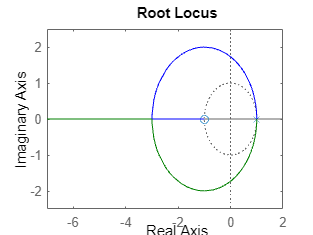

%% QUEREMOS UMA PORTENTAGEM DE OVERSHOOT 15%
%% Te menos de 25
%% TEMPO DE SUBIDA 1S

%% fazer o calculo e aonde no mapa precisa alocar
%% achar ecsi e omega m 
%% Quais regiões dos polos que deveremos estar com nossos polos??

rlocus(sysposdigital);

%% não sabemos a area não usar no relatorio

%% vamos usar isso
rltool(sysposdigital);
%% ttol box contrl system design

rltool(sysveldigital);
%% comando só pra achar ganho que precisamos botão direito edit compensator ou bloco c


## SIMULAR SISTEMA PARA VARIAS ENTRADAS

%% simulink
simulink